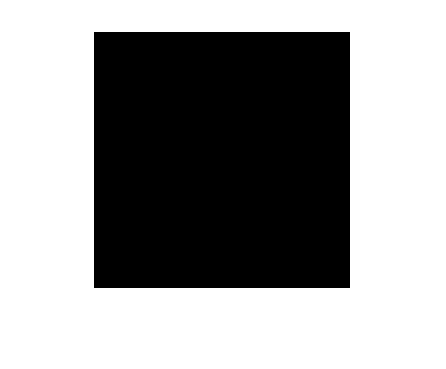

clear all
clc

mapo=zeros(256,256,3); %Genero matriz de la imagen con zeros
imshow(uint8(mapo)) %muestro imagen del plano vacío

p=(rand(16,2))*2.5*100; %genero matriz de números random con cordenas X,Y 
p=round(p);

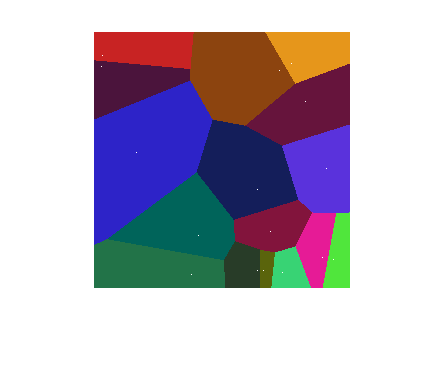


%localizo los puntos el otro mapa para conocer su posición
for i=1:16
    mapo(p(i,1),p(i,2),1)=255;
    mapo(p(i,1),p(i,2),2)=255;
    mapo(p(i,1),p(i,2),3)=255;
end
imshow(uint8(mapo))%muestro imagen del plano con los 16 puntos

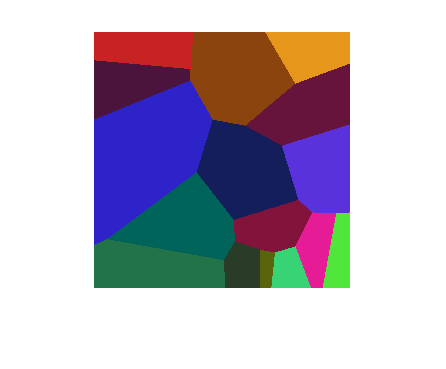

mapo=zeros(256,256,3); %Genero matriz de la imagen con zeros

for i=1:256
    for j=1:256
        distancia_a=900;
        pertenece=0;
        deltax=0;
        deltay=0;
        distancias=0;
        for k=1:16
            deltax=(p(k,1)-i);
            deltay=(p(k,2)-j);
            distancias=sqrt(deltax^2+deltay^2);
            if distancias < distancia_a
                distancia_a = distancias;
                pertenece=k;
            end
            
        end
        
        switch pertenece
                case 1
                    mapo(i,j,1)=0;
                    mapo(i,j,2)=100;
                    mapo(i,j,3)=90;
                case 2
                    mapo(i,j,1)=230;
                    mapo(i,j,2)=27;
                    mapo(i,j,3)=150;
                case 3
                    mapo(i,j,1)=230;
                    mapo(i,j,2)=150;
                    mapo(i,j,3)=27;
                case 4
                    mapo(i,j,1)=80;
                    mapo(i,j,2)=230;
                    mapo(i,j,3)=60;
                case 5
                    mapo(i,j,1)=20;
                    mapo(i,j,2)=30;
                    mapo(i,j,3)=90;
                case 6
                    mapo(i,j,1)=200;
                    mapo(i,j,2)=35;
                    mapo(i,j,3)=35;
                case 7
                    mapo(i,j,1)=102;
                    mapo(i,j,2)=20;
                    mapo(i,j,3)=60;
                case 8
                    mapo(i,j,1)=90;
                    mapo(i,j,2)=50;
                    mapo(i,j,3)=220;
                case 9
                    mapo(i,j,1)=90;
                    mapo(i,j,2)=100;
                    mapo(i,j,3)=12;
                case 10
                    mapo(i,j,1)=56;
                    mapo(i,j,2)=211;
                    mapo(i,j,3)=116;
                case 11
                    mapo(i,j,1)=140;
                    mapo(i,j,2)=68;
                    mapo(i,j,3)=15;
                case 12
                    mapo(i,j,1)=34;
                    mapo(i,j,2)=115;
                    mapo(i,j,3)=72;
                case 13
                    mapo(i,j,1)=40;
                    mapo(i,j,2)=60;
                    mapo(i,j,3)=40;
                case 14
                    mapo(i,j,1)=45;
                    mapo(i,j,2)=35;
                    mapo(i,j,3)=200;
                case 15
                    mapo(i,j,1)=130;
                    mapo(i,j,2)=20;
                    mapo(i,j,3)=60;
                case 16
                    mapo(i,j,1)=75;
                    mapo(i,j,2)=20;
                    mapo(i,j,3)=60;
            end
    end
end

imshow(uint8(mapo))%muestro imagen del plano con los 16 puntos